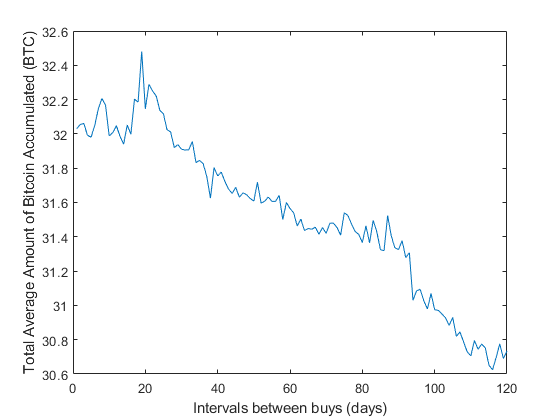


format bank
%price_data = readtable("Binance_BTCUSDT_d.csv"); %binance data up to 2017
%daily_close = (table2array(price_data(:,7)));
max_time_frame = 120;
BTC_position = zeros(max_time_frame,max_time_frame);
USD_position = zeros(max_time_frame,max_time_frame);
sampled_data = zeros(6,6);
price_data = readtable("BNC BLX, 1D.csv"); %bitcoin data since 2010
daily_buy_in = 10;

daily_close = table2array(price_data(1226:end,5));

% plot(1:2643, log10(daily_close))
% ylabel("log of BTC price ($)");
% xlabel("Days since 2013 bear bullmarket peak");

for i = 1:max_time_frame
    daily_closef = table2array(price_data(i+1225:end,5)); %take data since 2013 crash
    figure(i)
    [BTC_position(:,i), USD_position(:,i)]= accumulatedAmountDCA(daily_closef, daily_buy_in);
    
end

averageBTC = mean(BTC_position);
averageUSD = mean(USD_position);
figure(2)
plot(1:max_time_frame, averageBTC);
ylabel("Total Average Amount of Bitcoin Accumulated (BTC)");
xlabel("Intervals between buys (days)");


sample_time_frames = [19 60 30 14 7 3 1];

for i = 1:7;
    
     sampled_data(i,1) = sample_time_frames(i);
     sampled_data(i,2) = averageBTC(1,sample_time_frames(i));
     sampled_data(i,3) = averageUSD(1,sample_time_frames(i));
     sampled_data(i,4) = averageBTC(1,sample_time_frames(i)) * daily_close(end);
     sampled_data(i,5) = sampled_data(i,4) / averageUSD(1,sample_time_frames(i));
     sampled_data(i,6) =  ((sampled_data(i,4) -  sampled_data(1,4)) /  sampled_data(1,4)) * 100;
end
    
T = array2table(sampled_data, "VariableNames", ["DCA Interval (days)", "Final BTC Position", "Amount of USD Invested", "Final USD Value (Feb 22)","Increased Initial Investement","Relative to Most Efficient (%)"])

T = 7×6 table
    DCA Interval (days)    Final BTC Position    Amount of USD Invested    Final USD Value (Feb 22)    Increased Initial Investement    Relative to Most Efficient (%)
    ___________________    __________________    ______________________    ________________________    _____________________________    ______________________________

           19.00                 32.48                  26552.00                  1588613.71                       59.83                             0.00             
           60.00                 31.57                  26132.58                  1543839.03                       59.08                            -2.82             
           30.00                 31.91                  26435.67                  1560737.45                     


%Data = BuyTheDip(daily_close, 100);
%Ratio = Data(:,1)/Data(:,3)

function [BTC_final, USD_invested] = accumulatedAmountDCA(daily_close, daily_buy_in)

    max_time_frame = 120;
    v = zeros(1, max_time_frame);


    for q = 1:max_time_frame
        interval_close = daily_close(1:q:end);
        order_size = daily_buy_in * q;
   
    BTC_position = 0;
    money_invested = 0;
    for i = 1:size(interval_close);
        BTC_position = BTC_position + (order_size / interval_close(i));
        money_invested = order_size + money_invested;
    end
        v(q,1) = BTC_position;
        v(q,2) = money_invested;
    end
    BTC_final = v(:,1);
    USD_invested = v(:,2);
end

% function [Data] = BuyTheDip(daily_close, dip_buy_amount)
%     dip_percentages = 20:5:80;
%     temp = zeros(13,3);
%     lengthArray = length(daily_close);
%     for q = 1:13
%     figure(q)
%     
%     plot(1:2643, daily_close)
%     title("Buy-in points if the condition is a " + int2str(dip_percentages(q)) + "% dip")
%     ylabel("log of BTC price ($)");
%     set(gca, 'YScale', 'log')
%     xlabel("Days since 2013 bear bullmarket peak");
%     xlim([0 lengthArray]);
%     local_top = daily_close(1);
% 
%     number_of_dips = 0;
%     BTC_position = 0;
%     money_invested = 0;
%     dip_pecentage = dip_percentages(q)
%     for i = 1:lengthArray;
%         if(daily_close(i) >= local_top);
%             local_top = daily_close(i);
%             %top_index = i;
%         elseif(((local_top-daily_close(i))/local_top) * 100 >= dip_pecentage);
% 
%             local_top = daily_close(i);
%             %xline(top_index);
%             xline(i,"--r");
%             
%             number_of_dips = number_of_dips +1;
%             %buy_multiplier = 1/(1-(dip_pecentage/100) + 0.1);
%             buy_multiplier = 1;  
%             buy_amount = dip_buy_amount * buy_multiplier;
%             BTC_position = BTC_position + buy_amount/daily_close(i);
%             money_invested = money_invested + buy_amount;
% 
%         end
%     end
% 
%     
%     
%     temp(q,1) = BTC_position;
%     temp(q,2) = money_invested;
%     temp(q,3) = number_of_dips;
%     end
% 
% Data = temp;
% end